# Codigos de Proyecto 

- Sección: 4

- N° de grupo: 6

- Titulo del Proyecto: Simulación numérica del control PI de nivel en un tanque cónico no lineal

- Integrante 1 (líder): Silva Mena, David Manuel (202310120) - participación: 100 %

- Integrante 2: Aquino Pachas, Walter Sebastian (202410070) - participación: 100 %

- Integrante 3: Cahua Roman, Matias Alonso (202510278) - participación: 100 %

- Integrante 4: Carrillo Yalan, Sebastian Alexis (202210074) - participación: 100 %

- Integrante 5: Franco Palomino, Mathías Nicolás (202410321) - participación: 100 %

**Observación:** todos los integrantes participaron con 100 %. Código ejecutado en MATLAB R2026a.

- No olvidar añadir el porcentaje de participación.

- Incluir comentarios relevantes para entender el codigo, tener en cuenta que comentarios de IA anularan la entrega

- El codgio debe de tener una identacion adecuada para facilitar su lectura

- El codigo debe der replicable en cualquier computadora (Uso adecuado de semillas para funciones)

- Las funciones principales deben de ir en la parte inferior de este archivo

- Titulos de los codigos deben reflejar su funcionalidad

## Código 1: Parámetros, equilibrio, linealización y sintonía del PI

clear; clc; close all
rng(0)                              % semilla fija (el modelo es determinista)

% Parámetros del tanque cónico (Urrea y Páez, 2021)
p.H = 73;                           % altura del tanque (cm)
p.R = 19.25;                        % radio superior (cm)
p.kv = 22;                          % coeficiente de descarga (cm^(5/2)/s)
p.alpha = p.H^2/(pi*p.R^2);         % H^2/(pi R^2)
p.beta = p.alpha*p.kv;              % alpha*kv (cm^(5/2)/s)
p.Qmin = 0;   p.Qmax = 400;         % límites del caudal de entrada (cm^3/s)
p.hmin = 10;  p.hmax = 60;          % rango útil del nivel (cm)

% Punto de operación y caudal de equilibrio
p.hs = 40;                          % nivel de operación (cm)
p.Ls = 0;                           % carga nominal (cm^3/s)
p.Qs = p.Ls + p.kv*sqrt(p.hs);      % Q de equilibrio (cm^3/s)

% Linealización: d(dh)/dt = -a*dh + b*(dQ - dL)
a = p.beta/(2*p.hs^(5/2));
b = p.alpha/p.hs^2;
Ks = b/a;                           % ganancia local (s/cm^2)
tau_s = 1/a;                        % constante de tiempo local (s)

% Verificación simbólica de las derivadas parciales
syms hh QQ LL
fs = p.alpha*(QQ - LL)*hh^(-2) - p.beta*hh^(-3/2);
dfdh = double(subs(diff(fs, hh), [hh QQ LL], [p.hs p.Qs p.Ls]));
dfdQ = double(subs(diff(fs, QQ), [hh QQ LL], [p.hs p.Qs p.Ls]));

% Sintonía del PI por asignación de polos: s^2 + (a + b*Kp)s + b*Ki = 0
zeta = 0.8;                         % amortiguamiento deseado
ts_d = 200;                         % tiempo de establecimiento deseado (s)
wn = 4/(zeta*ts_d);                 % frecuencia natural (rad/s)
p.Kp = (2*zeta*wn - a)/b;           % (cm^2/s)
p.Ki = wn^2/b;                      % (cm^2/s^2)

% Polos del lazo cerrado lineal en (dh, z)
Acl = [-(a + b*p.Kp), b*p.Ki; -1, 0];
lam = eig(Acl);
[dtE, dtR, dtC] = limite_paso(Acl); % pasos máximos estables de Euler, RK4 y Cash-Karp

fprintf('alpha = %.4f, beta = %.2f cm^(5/2)/s\n', p.alpha, p.beta)

alpha = 4.5776, beta = 100.71 cm^(5/2)/s


fprintf('Qs = %.2f cm^3/s, Ks = %.4f s/cm^2, tau_s = %.2f s\n', p.Qs, Ks, tau_s)

Qs = 139.14 cm^3/s, Ks = 0.5750 s/cm^2, tau_s = 200.97 s


fprintf('df/dh: %.6e (analítica) %.6e (syms)\n', -a, dfdh)

df/dh: -4.975962e-03 (analítica) -4.975962e-03 (syms)


fprintf('df/dQ: %.6e (analítica) %.6e (syms)\n', b, dfdQ)

df/dQ: 2.860977e-03 (analítica) 2.860977e-03 (syms)


fprintf('Kp = %.4f cm^2/s, Ki = %.5f cm^2/s^2\n', p.Kp, p.Ki)

Kp = 12.2420 cm^2/s, Ki = 0.21846 cm^2/s^2


fprintf('Polos: %.5f %+.5fi\n', [real(lam) imag(lam)]')

Polos: -0.02000 +0.01500i
Polos: -0.02000 -0.01500i


fprintf('Paso máximo estable (lineal): Euler %.2f s, RK4 %.2f s, Cash-Karp %.2f s\n', ...
    dtE, dtR, dtC)

Paso máximo estable (lineal): Euler 64.00 s, RK4 111.66 s, Cash-Karp 146.38 s



% Escenario base: escalón de consigna y perturbación de carga
p.hsp0 = 40;  p.dhsp = 5;  p.tsp = 100;     % consigna 40 -> 45 cm en t = 100 s
p.Lamp = 30;  p.tL = 800;                    % carga L = 30 cm^3/s en t = 800 s
tf = 1500;                                   % horizonte (s)
tramos = [0 p.tsp p.tL tf];                  % instantes de discontinuidad
y0 = [p.hs; 0];                              % estado inicial [h; z]
f = @(t, y, tu) modelo(y, entradas(tu, p), p);

% Opciones de Cash-Karp
ck = struct('rtol', 1e-6, 'atol', 1e-6, 'h0', 1, 'S', 0.9, 'fmin', 0.2, 'fmax', 5);

Parametro = ["H"; "R"; "kv"; "alpha"; "beta"; "hs"; "Qs"; "Kp"; "Ki"];
Valor = [p.H; p.R; p.kv; p.alpha; p.beta; p.hs; p.Qs; p.Kp; p.Ki];
disp(table(Parametro, Valor))

    Parametro     Valor 
    _________    _______

     "H"              73
     "R"           19.25
     "kv"             22
     "alpha"      4.5776
     "beta"       100.71
     "hs"             40
     "Qs"         139.14
     "Kp"         12.242
     "Ki"        0.21846



## Código 2: Caso base con Euler, RK4 y Cash-Karp

% Solución de referencia en una malla densa
tq = (0:tf*10)'/10;
Yq = referencia(f, tramos, y0, tq);
Qq = caudal(tq, Yq, p);

% Euler y RK4 con dt = 2, 1 y 0.5 s; Cash-Karp con rtol = 1e-6
dt_base = [2 1 0.5];
Metodo = strings(0); Param = []; Pasos = []; nF = []; Einf = [];
Mp = []; ts = []; dmax = [];
sol = struct();
for k = 1:numel(dt_base)
    [t1, Y1, n1] = euler(f, tramos, y0, dt_base(k));
    [t2, Y2, n2] = rk4(f, tramos, y0, dt_base(k));
    sol.eu{k} = {t1, Y1};  sol.rk{k} = {t2, Y2};
    Metodo = [Metodo; "Euler"; "RK4"];
    Param = [Param; dt_base(k); dt_base(k)];
    Pasos = [Pasos; numel(t1)-1; numel(t2)-1];
    nF = [nF; n1; n2];
    Einf = [Einf; error_inf(t1, Y1, f, tramos, y0); error_inf(t2, Y2, f, tramos, y0)];
    m1 = indicadores(t1, Y1, p);  m2 = indicadores(t2, Y2, p);
    Mp = [Mp; m1.Mp; m2.Mp];  ts = [ts; m1.ts; m2.ts];  dmax = [dmax; m1.dmax; m2.dmax];
end
[t3, Y3, n3, est3] = cash_karp(f, tramos, y0, ck);
m3 = indicadores(t3, Y3, p);  mr = indicadores(tq, Yq, p);
Metodo = [Metodo; "Cash-Karp"; "Referencia"];
Param = [Param; ck.rtol; 1e-12];
Pasos = [Pasos; est3.nacc; NaN];
nF = [nF; n3; NaN];
Einf = [Einf; error_inf(t3, Y3, f, tramos, y0); 0];
Mp = [Mp; m3.Mp; mr.Mp];  ts = [ts; m3.ts; mr.ts];  dmax = [dmax; m3.dmax; mr.dmax];
T_base = table(Metodo, Param, Pasos, nF, Einf, Mp, ts, dmax);
disp(T_base)

       Metodo       Param    Pasos     nF         Einf         Mp        ts       dmax 
    ____________    _____    _____    _____    __________    ______    ______    ______

    "Euler"             2     750       750      0.074661    14.582    214.22    1.4424
    "RK4"               2     750      3000    6.0233e-08    13.883    218.65    1.4057
    "Euler"             1    1500      1500      0.036908    14.226    216.44    1.4238
    "RK4"               1    1500      6000    3.7298e-09    13.883    218.65    1.4059
    "Euler"           0.5    3000      3000      0.018351    14.053    217.54    1.4148
    "RK4"             0.5    3000     12000    2.3206e-10    13.883    218.64    1.4059
    "Cash-Karp"     1e-06      60       396    3.6275e-06    13.881    219.25    1.4029
    "Referencia"    1e-12     NaN       NaN             0    13.883    218.64    1.4059



fprintf('Referencia: tr = %.2f s, Mp = %.3f %%, ts = %.2f s, ess = %.2e cm\n', ...
    mr.tr, mr.Mp, mr.ts, mr.ess)

Referencia: tr = 42.61 s, Mp = 13.883 %, ts = 218.64 s, ess = 5.97e-05 cm


fprintf('Carga: dh_max = %.4f cm, t_rec = %.2f s, IAE = %.3f cm s, Qmax = %.2f\n', ...
    mr.dmax, mr.trec, mr.IAE, max(Qq))

Carga: dh_max = 1.4059 cm, t_rec = 274.43 s, IAE = 148.836 cm s, Qmax = 200.35


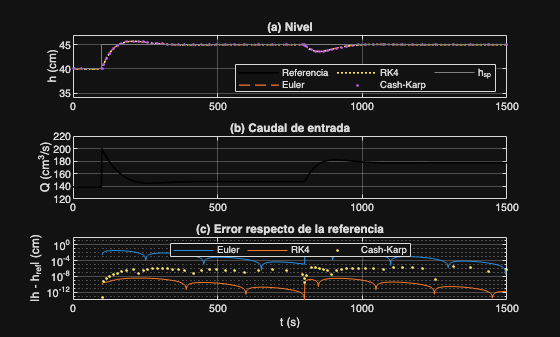


% Respuesta y error puntual de cada método
figure('Name', 'fig_caso_base')
subplot(3,1,1)
plot(tq, Yq(:,1), 'k', 'LineWidth', 1.2); hold on
plot(sol.eu{2}{1}, sol.eu{2}{2}(:,1), '--', 'LineWidth', 1)
plot(sol.rk{2}{1}, sol.rk{2}{2}(:,1), ':', 'LineWidth', 1.2)
plot(t3, Y3(:,1), '.', 'MarkerSize', 6)
stairs([0 p.tsp tf], [p.hsp0 p.hsp0+p.dhsp p.hsp0+p.dhsp], 'Color', [0.5 0.5 0.5])
hold off; grid on
ylabel('h (cm)'); xlim([0 tf]); ylim([34 47])
legend('Referencia', 'Euler', 'RK4', 'Cash-Karp', 'h_{sp}', ...
    'NumColumns', 3, 'Location', 'southeast')
title('(a) Nivel')
subplot(3,1,2)
plot(tq, Qq, 'k', 'LineWidth', 1.2); grid on
ylabel('Q (cm^3/s)'); xlim([0 tf]); ylim([120 220]); title('(b) Caudal de entrada')
subplot(3,1,3)
e1 = abs(sol.eu{2}{2}(:,1) - referencia(f, tramos, y0, sol.eu{2}{1})*[1;0]);
e2 = abs(sol.rk{2}{2}(:,1) - referencia(f, tramos, y0, sol.rk{2}{1})*[1;0]);
e3 = abs(Y3(:,1) - referencia(f, tramos, y0, t3)*[1;0]);
semilogy(sol.eu{2}{1}, e1, sol.rk{2}{1}, e2, t3, e3, '.', 'MarkerSize', 6); grid on
xlabel('t (s)'); ylabel('|h - h_{ref}| (cm)')
xlim([0 tf]); ylim([1e-14 1e2]); yticks(10.^(-12:4:0))
legend('Euler', 'RK4', 'Cash-Karp', 'Orientation', 'horizontal', 'Location', 'north')
title('(c) Error respecto de la referencia')

## Código 3: Convergencia y orden observado

% Verificación de la referencia en t = 0, 50, ..., 1500 s
tv = (0:50:tf)';
Yv12 = referencia(f, tramos, y0, tv);
Yv10 = referencia(f, tramos, y0, tv, 1e-10);
[t2, Y2] = rk4(f, tramos, y0, 0.0625);
Yv = Y2(ismember(t2, tv), :);
fprintf('max|ref(1e-12) - ref(1e-10)| = %.2e cm\n', max(abs(Yv12(:,1) - Yv10(:,1))))

max|ref(1e-12) - ref(1e-10)| = 4.09e-10 cm


fprintf('max|ref(1e-12) - RK4(dt = 0.0625)| = %.2e cm\n', max(abs(Yv12(:,1) - Yv(:,1))))

max|ref(1e-12) - RK4(dt = 0.0625)| = 5.07e-12 cm



% Integración por tramos (el paso no cruza t = 100 s ni t = 800 s)
dt_c = [4 2 1 0.5 0.25 0.125]';
E_eu = zeros(size(dt_c)); E_rk = E_eu; nF_eu = E_eu; nF_rk = E_eu;
for k = 1:numel(dt_c)
    [t1, Y1, nF_eu(k)] = euler(f, tramos, y0, dt_c(k));
    [t2, Y2, nF_rk(k)] = rk4(f, tramos, y0, dt_c(k));
    E_eu(k) = error_inf(t1, Y1, f, tramos, y0);
    E_rk(k) = error_inf(t2, Y2, f, tramos, y0);
end
p_eu = [NaN; log2(E_eu(1:end-1)./E_eu(2:end))];
p_rk = [NaN; log2(E_rk(1:end-1)./E_rk(2:end))];
T_conv = table(dt_c, E_eu, p_eu, E_rk, p_rk, 'VariableNames', ...
    {'dt', 'E_Euler', 'p_Euler', 'E_RK4', 'p_RK4'});
disp(T_conv)

     dt       E_Euler     p_Euler      E_RK4       p_RK4 
    _____    _________    _______    __________    ______

        4      0.15284       NaN     9.8152e-07       NaN
        2     0.074661    1.0336     6.0233e-08    4.0264
        1     0.036908    1.0164     3.7298e-09    4.0134
      0.5     0.018351    1.0081     2.3206e-10    4.0065
     0.25    0.0091499     1.004     1.4452e-11    4.0051
    0.125    0.0045686     1.002      9.166e-13    3.9789




% RK4 con malla uniforme que atraviesa los escalones (sin cortar)
fsin = @(t, y, tu) modelo(y, entradas(t, p), p);
dt_s = [3 1.5 0.75 0.375 0.1875]';
Es_rk = zeros(size(dt_s));
for k = 1:numel(dt_s)
    [t2, Y2] = rk4(fsin, [0 tf], y0, dt_s(k));
    Es_rk(k) = error_inf(t2, Y2, f, tramos, y0);
end
ps_rk = [NaN; log2(Es_rk(1:end-1)./Es_rk(2:end))];
disp(table(dt_s, Es_rk, ps_rk, 'VariableNames', {'dt', 'E_RK4_sin_cortar', 'p'}))

      dt      E_RK4_sin_cortar       p   
    ______    ________________    _______

         3        0.082455            NaN
       1.5        0.043108        0.93564
      0.75        0.021557        0.99983
     0.375        0.010903        0.98344
    0.1875       0.0054514        0.99999



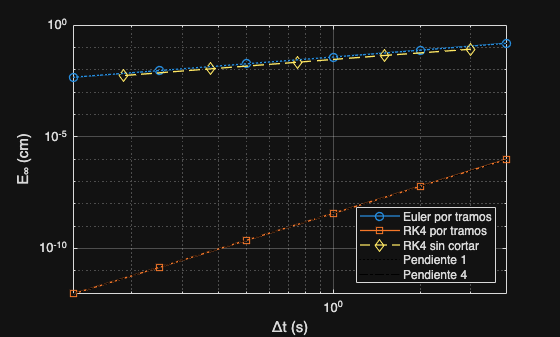


figure('Name', 'fig_convergencia')
loglog(dt_c, E_eu, 'o-', dt_c, E_rk, 's-', dt_s, Es_rk, 'd--', 'LineWidth', 1); hold on
loglog(dt_c, E_eu(3)*(dt_c/dt_c(3)).^1, 'k:', dt_c, E_rk(3)*(dt_c/dt_c(3)).^4, 'k-.')
hold off; grid on
xlabel('\Deltat (s)'); ylabel('E_\infty (cm)')
legend('Euler por tramos', 'RK4 por tramos', 'RK4 sin cortar', ...
    'Pendiente 1', 'Pendiente 4', 'Location', 'southeast')

## Código 4: Cash-Karp con distintas tolerancias y su costo

rtol = 10.^(-2:-1:-8)';
Acept = zeros(size(rtol)); Rech = Acept; nF_ck = Acept; E_ck = Acept; t_ck = Acept;
for k = 1:numel(rtol)
    op = ck;  op.rtol = rtol(k);  op.atol = rtol(k);
    [t3, Y3, nF_ck(k), est] = cash_karp(f, tramos, y0, op);
    Acept(k) = est.nacc;  Rech(k) = est.nrec;
    E_ck(k) = error_inf(t3, Y3, f, tramos, y0);
    t_ck(k) = 1e3*timeit(@() cash_karp(f, tramos, y0, op));
end
p_tol = [NaN; log10(E_ck(1:end-1)./E_ck(2:end))];
T_ck = table(rtol, Acept, Rech, nF_ck, E_ck, p_tol, t_ck, 'VariableNames', ...
    {'rtol', 'Aceptados', 'Rechazados', 'nF', 'E_inf', 'Pendiente', 't_ms'});
disp(T_ck)

     rtol     Aceptados    Rechazados    nF       E_inf       Pendiente     t_ms  
    ______    _________    __________    ___    __________    _________    _______

      0.01        22           2         144       0.12619         NaN      0.2721
     0.001        26           3         174     0.0048539      1.4149     0.34972
    0.0001        32           2         204    0.00028397      1.2328     0.39298
     1e-05        43           5         288    3.6299e-05     0.89338     0.51844
     1e-06        60           6         396    3.6275e-06      1.0003     0.66198
     1e-07        86           8         564    1.9879e-07      1.2612     0.89617
     1e-08       129           9         828    3.9199e-08     0.70513      1.2419




% Tiempo de Euler y RK4 en la misma malla de pasos
t_eu = zeros(size(dt_c)); t_rk = t_eu;
for k = 1:numel(dt_c)
    t_eu(k) = 1e3*timeit(@() euler(f, tramos, y0, dt_c(k)));
    t_rk(k) = 1e3*timeit(@() rk4(f, tramos, y0, dt_c(k)));
end
disp(table(dt_c, nF_eu, t_eu, nF_rk, t_rk, 'VariableNames', ...
    {'dt', 'nF_Euler', 't_Euler_ms', 'nF_RK4', 't_RK4_ms'}))

     dt      nF_Euler    t_Euler_ms    nF_RK4    t_RK4_ms
    _____    ________    __________    ______    ________

        4       375       0.47019       1500      1.2827 
        2       750       0.82444       3000      2.9111 
        1      1500        1.3881       6000      4.1372 
      0.5      3000        2.6432      12000      8.3385 
     0.25      6000        6.0885      24000      17.647 
    0.125     12000        16.421      48000      40.608 




% Costo mínimo para alcanzar E_inf <= 1e-2 cm
Emeta = 1e-2;
fprintf('nF para E <= %.0e cm: Euler %d, RK4 %d, Cash-Karp %d\n', Emeta, ...
    min(nF_eu(E_eu <= Emeta)), min(nF_rk(E_rk <= Emeta)), min(nF_ck(E_ck <= Emeta)))

nF para E <= 1e-02 cm: Euler 6000, RK4 1500, Cash-Karp 174


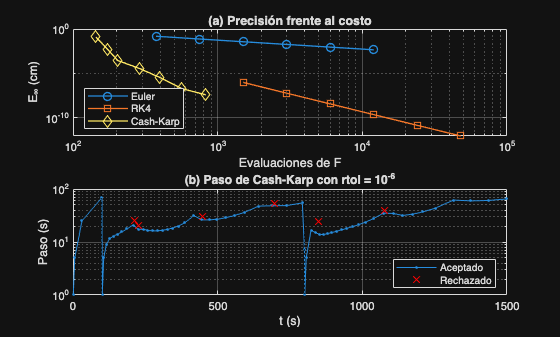


% Historial de pasos con rtol = 1e-6
[t3, ~, ~, est] = cash_karp(f, tramos, y0, ck);

figure('Name', 'fig_costo')
subplot(2,1,1)
loglog(nF_eu, E_eu, 'o-', nF_rk, E_rk, 's-', nF_ck, E_ck, 'd-', 'LineWidth', 1); grid on
xlabel('Evaluaciones de F'); ylabel('E_\infty (cm)')
legend('Euler', 'RK4', 'Cash-Karp', 'Location', 'southwest')
title('(a) Precisión frente al costo')
subplot(2,1,2)
semilogy(est.tacc, est.hacc, '.-'); hold on
semilogy(est.trej, est.hrej, 'rx', 'MarkerSize', 7); hold off; grid on
xline([p.tsp p.tL], ':k')
xlabel('t (s)'); ylabel('Paso (s)'); xlim([0 tf])
legend('Aceptado', 'Rechazado', 'Location', 'southeast')
title('(b) Paso de Cash-Karp con rtol = 10^{-6}')

## Código 5: Estabilidad con pasos grandes (h <= 0 o fuera del rango físico)

% Paso máximo estable del lazo lineal en distintos niveles de operación
hop = (10:0.5:60)';
dtE_h = zeros(size(hop)); dtR_h = dtE_h; dtC_h = dtE_h;
for k = 1:numel(hop)
    [~, dtE_h(k), dtR_h(k), dtC_h(k)] = limite_paso_nivel(p, hop(k));
end

% Escenarios sin escalones: A (30 -> 40 cm) y B (25 -> 20 cm)
esc = [30 40; 25 20];
dt_e = [5 10 15 20 30 50 60 75 100 125 150]';
estado = strings(numel(dt_e), 4);
for j = 1:2
    pe = p;  pe.hsp0 = esc(j,2);  pe.dhsp = 0;  pe.Lamp = 0;
    fe = @(t, y, tu) modelo(y, entradas(tu, pe), pe);
    ye = [esc(j,1); 0];
    for hj = esc(j,:)
        [~, dE, dR, dC] = limite_paso_nivel(pe, hj);
        fprintf('Esc. %d, h = %d cm: límite Euler %.2f s, RK4 %.2f s, CK %.2f s\n', ...
            j, hj, dE, dR, dC)
    end
    for k = 1:numel(dt_e)
        [t1, Y1, ~, fa1] = euler(fe, [0 tf], ye, dt_e(k));
        [t2, Y2, ~, fa2] = rk4(fe, [0 tf], ye, dt_e(k));
        estado(k, 2*j-1) = clasificar(t1, Y1, fa1, pe);
        estado(k, 2*j) = clasificar(t2, Y2, fa2, pe);
        if j == 1, solA{k} = {t1, Y1, t2, Y2}; end
    end
    % Cash-Karp con tolerancia holgada y paso inicial grande
    op = ck;  op.rtol = 1e-3;  op.atol = 1e-3;  op.h0 = 150;
    [t3, Y3, ~, est] = cash_karp(fe, [0 tf], ye, op);
    hpas = diff(t3);
    hmed = median(hpas(t3(2:end) > tf/2));           % paso mediano en la segunda mitad
    fprintf('Cash-Karp (rtol = 1e-3): %d aceptados, %d rechazados, paso mediano %.2f s, %s\n', ...
        est.nacc, est.nrec, hmed, clasificar(t3, Y3, est.falla, pe))
end

Esc. 1, h = 30 cm: límite Euler 39.64 s, RK4 55.20 s, CK 74.01 s
Esc. 1, h = 40 cm: límite Euler 64.00 s, RK4 111.66 s, CK 146.38 s


Cash-Karp (rtol = 1e-3): 20 aceptados, 6 rechazados, paso mediano 142.86 s, converge


Esc. 2, h = 25 cm: límite Euler 22.86 s, RK4 31.84 s, CK 42.69 s
Esc. 2, h = 20 cm: límite Euler 13.18 s, RK4 18.35 s, CK 24.60 s


Cash-Karp (rtol = 1e-3): 61 aceptados, 11 rechazados, paso mediano 23.79 s, converge


T_est = table(dt_e, estado(:,1), estado(:,2), estado(:,3), estado(:,4), ...
    'VariableNames', {'dt', 'Euler_A', 'RK4_A', 'Euler_B', 'RK4_B'});
disp(T_est)

    dt      Euler_A           RK4_A              Euler_B              RK4_B      
    ___    __________    ________________    ________________    ________________

      5    "converge"    "converge"          "converge"          "converge"      
     10    "converge"    "converge"          "converge"          "converge"      
     15    "converge"    "converge"          "fuera de rango"    "converge"      
     20    "converge"    "converge"          "fuera de rango"    "h <= 0"        
     30    "converge"    "converge"          "h <= 0"            "h <= 0"        
     50    "h <= 0"      "converge"          "h <= 0"            "h <= 0"        
     60    "h <= 0"      "converge"          "fuera de rango"    "fuera de rango"
     75    "h <= 0"      "fuera de rango"    "fuera de rango"    "h <= 0"        
    100    "h <= 0"      "h <= 0"            "fuera de rango"    "h <= 0"        
    125    "h <= 0"      "h <= 0"            "h <= 0"            "fuera de rango"
    150    "h <

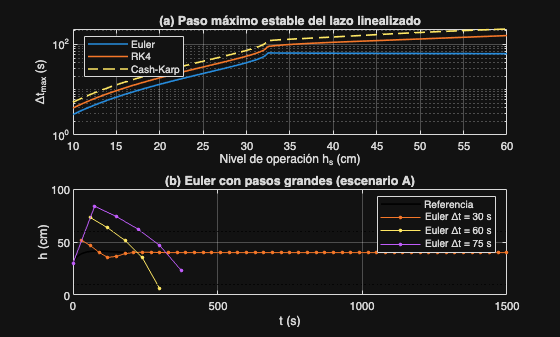


pA = p;  pA.hsp0 = 40;  pA.dhsp = 0;  pA.Lamp = 0;
fA = @(t, y, tu) modelo(y, entradas(tu, pA), pA);
tqA = (0:tf*2)'/2;
YqA = referencia(fA, [0 tf], [30; 0], tqA);

figure('Name', 'fig_estabilidad')
subplot(2,1,1)
semilogy(hop, dtE_h, hop, dtR_h, hop, dtC_h, '--', 'LineWidth', 1.2); grid on
xlabel('Nivel de operación h_s (cm)'); ylabel('\Deltat_{max} (s)')
legend('Euler', 'RK4', 'Cash-Karp', 'Location', 'northwest')
title('(a) Paso máximo estable del lazo linealizado')
subplot(2,1,2)
plot(tqA, YqA(:,1), 'k', 'LineWidth', 1.2); hold on
ksel = find(ismember(dt_e, [30 60 75]));
for k = ksel'
    plot(solA{k}{1}, solA{k}{2}(:,1), '.-', 'MarkerSize', 8)
end
yline([p.hmin p.hmax], ':k'); hold off; grid on
xlabel('t (s)'); ylabel('h (cm)'); xlim([0 tf])
legend('Referencia', 'Euler \Deltat = 30 s', 'Euler \Deltat = 60 s', ...
    'Euler \Deltat = 75 s', 'Location', 'northeast')
title('(b) Euler con pasos grandes (escenario A)')

## Código 6: Análisis paramétrico

% Variación de un parámetro a la vez en el escenario base
casos = {"Nominal", "-", 1; "alpha", "alpha", 0.8; "alpha", "alpha", 1.2; ...
    "beta", "beta", 0.8; "beta", "beta", 1.2; "Kp", "Kp", 0.5; "Kp", "Kp", 2; ...
    "Ki", "Ki", 0.5; "Ki", "Ki", 2; "L", "Lamp", 10/30; "L", "Lamp", 60/30};
nc = size(casos, 1);
Caso = strings(nc,1); Factor = zeros(nc,1); Mp6 = Factor; ts6 = Factor; dmax6 = Factor;
trec6 = Factor; Qmax6 = Factor; E_eu6 = Factor; E_rk6 = Factor;
Acc6 = Factor; Rec6 = Factor;
resp = cell(nc, 1);
for k = 1:nc
    pk = p;
    if casos{k,2} ~= "-"
        pk.(casos{k,2}) = casos{k,3}*p.(casos{k,2});
    end
    pk.Qs = pk.Ls + (pk.beta/pk.alpha)*sqrt(pk.hs);  % equilibrio de la planta modificada
    fk = @(t, y, tu) modelo(y, entradas(tu, pk), pk);
    Yk = referencia(fk, tramos, y0, tq);
    mk = indicadores(tq, Yk, pk);
    [t1, Y1] = euler(fk, tramos, y0, 1);
    [t2, Y2] = rk4(fk, tramos, y0, 1);
    [~, ~, ~, est] = cash_karp(fk, tramos, y0, ck);
    Caso(k) = casos{k,1};  Factor(k) = casos{k,3};
    Mp6(k) = mk.Mp;  ts6(k) = mk.ts;  dmax6(k) = mk.dmax;  trec6(k) = mk.trec;
    Qmax6(k) = max(caudal(tq, Yk, pk));
    E_eu6(k) = error_inf(t1, Y1, fk, tramos, y0);
    E_rk6(k) = error_inf(t2, Y2, fk, tramos, y0);
    Acc6(k) = est.nacc;  Rec6(k) = est.nrec;
    resp{k} = Yk(:,1);
end
T_param = table(Caso, Factor, Mp6, ts6, dmax6, trec6, Qmax6, E_eu6, E_rk6, ...
    Acc6, Rec6, 'VariableNames', {'Caso', 'Factor', 'Mp', 'ts', 'dh_max', 't_rec', 'Q_max', ...
    'E_Euler', 'E_RK4', 'CK_acept', 'CK_rech'});
disp(T_param)

      Caso       Factor       Mp        ts      dh_max    t_rec     Q_max     E_Euler       E_RK4       CK_acept    CK_rech
    _________    _______    ______    ______    ______    ______    ______    ________    __________    ________    _______

    "Nominal"          1    13.883    218.64    1.4059    274.43    200.35    0.036908    3.7298e-09       60          6   
    "alpha"          0.8    15.145    243.46    1.3167     325.2    235.14    0.032002    2.0665e-09       60          7   
    "alpha"          1.2    12.825     200.6    1.4778    181.59    177.16    0.042315    9.9893e-09       61          4   
    "beta"           0.8    15.278     217.6    1.4257    284.75    172.52    0.037626    3.5337e-09       62          6   
    "beta"           1.2    12.542     219.4    1.3867    189.76    228.18    0.036242    4.0335e-09       59          5   
    "Kp"             0.5    28.335    348.75    1.8755    425.25    186.96    0.047097    9.5856e-09       76         11   
    "Kp


% Nivel inicial: regulación a 40 cm sin escalones
h0v = [15 25 35 45 55]';
t_h0 = 800;
p0 = p;  p0.hsp0 = 40;  p0.dhsp = 0;  p0.Lamp = 0;
f0 = @(t, y, tu) modelo(y, entradas(tu, p0), p0);
tq0 = (0:t_h0*10)'/10;
Mp0 = zeros(size(h0v)); ts0 = Mp0; Qmax0 = Mp0; tsat0 = Mp0; E_eu0 = Mp0; E_rk0 = Mp0;
Acc0 = Mp0; Rec0 = Mp0; resp0 = cell(size(h0v));
for k = 1:numel(h0v)
    yk = [h0v(k); 0];
    Yk = referencia(f0, [0 t_h0], yk, tq0);
    m0 = metricas_escalon(tq0, Yk(:,1), 0, t_h0, h0v(k), 40);
    Qk = caudal(tq0, Yk, p0);
    [t1, Y1] = euler(f0, [0 t_h0], yk, 1);
    [t2, Y2] = rk4(f0, [0 t_h0], yk, 1);
    [~, ~, ~, est] = cash_karp(f0, [0 t_h0], yk, ck);
    Mp0(k) = m0.Mp;  ts0(k) = m0.ts;  Qmax0(k) = max(Qk);
    tsat0(k) = 0.1*sum(Qk >= p.Qmax | Qk <= p.Qmin);
    E_eu0(k) = error_inf(t1, Y1, f0, [0 t_h0], yk);
    E_rk0(k) = error_inf(t2, Y2, f0, [0 t_h0], yk);
    Acc0(k) = est.nacc;  Rec0(k) = est.nrec;
    resp0{k} = Yk(:,1);
end
T_h0 = table(h0v, Mp0, ts0, Qmax0, tsat0, E_eu0, E_rk0, Acc0, Rec0, 'VariableNames', ...
    {'h0', 'Mp', 'ts', 'Q_max', 't_sat', 'E_Euler', 'E_RK4', 'CK_acept', 'CK_rech'});
disp(T_h0)

    h0      Mp        ts      Q_max     t_sat    E_Euler       E_RK4       CK_acept    CK_rech
    __    ______    ______    ______    _____    ________    __________    ________    _______

    15    9.1625    176.82       400     0.9       1.7478    0.00095794       56         10   
    25    12.128    186.99    322.77       0      0.29894    9.0588e-06       50          3   
    35    15.849    197.06    200.35       0     0.051417    2.9576e-08       45          3   
    45    20.293    207.37    141.66       0     0.045776    8.4193e-09       45          4   
    55    29.164    225.23    148.21    35.5      0.17198    0.00010777       53         10   



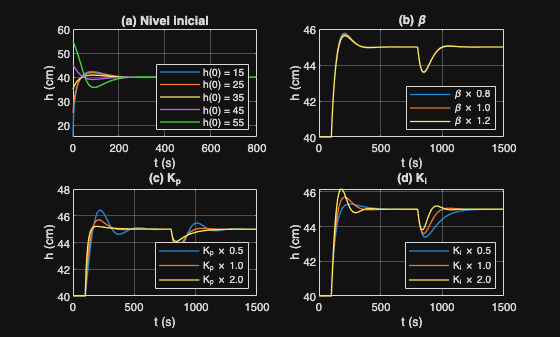


figure('Name', 'fig_sensibilidad')
subplot(2,2,1)
for k = 1:numel(h0v), plot(tq0, resp0{k}, 'LineWidth', 1); hold on, end
hold off; grid on; xlabel('t (s)'); ylabel('h (cm)')
legend(compose('h(0) = %d', h0v), 'Location', 'southeast'); title('(a) Nivel inicial')
grupos = {[2 1 3], [4 1 5], [6 1 7], [8 1 9]};
etiq = ["\alpha", "\beta", "K_p", "K_i"];
for g = 2:4
    subplot(2,2,g)
    for k = grupos{g}, plot(tq, resp{k}, 'LineWidth', 1); hold on, end
    hold off; grid on; xlim([0 tf]); xlabel('t (s)'); ylabel('h (cm)')
    legend(etiq(g) + " \times " + compose("%.1f", Factor(grupos{g})), ...
        'Location', 'southeast')
    title(sprintf('(%s) ', char('a' + g - 1)) + etiq(g))
end

## Código 7: Perturbación de carga y modelo no lineal frente al lineal

t7 = 800;
tq7 = (0:t7*10)'/10;
p7 = p;  p7.hsp0 = 40;  p7.tsp = 50;  p7.tL = 50;  p7.dhsp = 0;  p7.Lamp = 0;
tr7 = [0 50 t7];

% Escalones de consigna de distinto tamaño
dh7 = [-15 -10 -5 5 10 15]';
Mp_nl = zeros(size(dh7)); Mp_li = Mp_nl; ts_nl = Mp_nl; ts_li = Mp_nl; dif7 = Mp_nl;
Qn_nl = Mp_nl; Qx_nl = Mp_nl; ysp = cell(numel(dh7), 2);
for k = 1:numel(dh7)
    pk = p7;  pk.dhsp = dh7(k);
    fn = @(t, y, tu) modelo(y, entradas(tu, pk), pk);
    fl = @(t, y, tu) modelo_lineal(y, entradas(tu, pk), pk);
    Yn = referencia(fn, tr7, y0, tq7);
    Yl = referencia(fl, tr7, y0, tq7);
    mn = metricas_escalon(tq7, Yn(:,1), 50, t7, 40, 40 + dh7(k));
    ml = metricas_escalon(tq7, Yl(:,1), 50, t7, 40, 40 + dh7(k));
    Mp_nl(k) = mn.Mp;  Mp_li(k) = ml.Mp;  ts_nl(k) = mn.ts;  ts_li(k) = ml.ts;
    dif7(k) = max(abs(Yn(:,1) - Yl(:,1)));
    Qk = caudal(tq7, Yn, pk);
    Qn_nl(k) = min(Qk);  Qx_nl(k) = max(Qk);
    ysp{k,1} = (Yn(:,1) - 40)/dh7(k);  ysp{k,2} = (Yl(:,1) - 40)/dh7(k);
end
T_sp = table(dh7, Mp_nl, Mp_li, ts_nl, ts_li, dif7, Qn_nl, Qx_nl, 'VariableNames', ...
    {'dh_sp', 'Mp_NL', 'Mp_lin', 'ts_NL', 'ts_lin', 'max_dif', 'Q_min_NL', 'Q_max_NL'});
disp(T_sp)

    dh_sp    Mp_NL     Mp_lin    ts_NL     ts_lin    max_dif    Q_min_NL    Q_max_NL
    _____    ______    ______    ______    ______    _______    ________    ________

     -15     9.5818    14.312     157.5    204.72     2.6868          0      139.14 
     -10      9.678    12.649    167.06    201.13     1.0278      16.72      139.14 
      -5     11.256    12.649    184.35    201.13    0.24212      77.93      139.14 
       5     13.883    12.649    218.64    201.13     0.2167     139.14      200.35 
      10     14.981    12.649    237.16    201.13    0.82346     139.14      261.56 
      15     15.963    12.649    256.55    201.13     1.7647     139.14      322.77 




% Escalones de carga
L7 = [10 30 60]';
dmax_nl = zeros(size(L7)); dmax_li = dmax_nl; trec_nl = dmax_nl; trec_li = dmax_nl;
IAE_nl = dmax_nl; IAE_li = dmax_nl; yL = cell(numel(L7), 2);
for k = 1:numel(L7)
    pk = p7;  pk.Lamp = L7(k);
    fn = @(t, y, tu) modelo(y, entradas(tu, pk), pk);
    fl = @(t, y, tu) modelo_lineal(y, entradas(tu, pk), pk);
    Yn = referencia(fn, tr7, y0, tq7);
    Yl = referencia(fl, tr7, y0, tq7);
    mn = metricas_carga(tq7, Yn(:,1), 50, t7, 40, 0.05);
    ml = metricas_carga(tq7, Yl(:,1), 50, t7, 40, 0.05);
    dmax_nl(k) = mn.dmax;  dmax_li(k) = ml.dmax;
    trec_nl(k) = mn.trec;  trec_li(k) = ml.trec;
    IAE_nl(k) = mn.IAE;  IAE_li(k) = ml.IAE;
    yL{k,1} = Yn(:,1);  yL{k,2} = Yl(:,1);
end
T_L = table(L7, dmax_nl, dmax_li, trec_nl, trec_li, IAE_nl, IAE_li, 'VariableNames', ...
    {'L', 'dh_max_NL', 'dh_max_lin', 't_rec_NL', 't_rec_lin', 'IAE_NL', 'IAE_lin'});
disp(T_L)

    L     dh_max_NL    dh_max_lin    t_rec_NL    t_rec_lin    IAE_NL    IAE_lin
    __    _________    __________    ________    _________    ______    _______

    10     0.48688      0.48523       161.41      161.34      47.116    47.185 
    30      1.4707       1.4557       186.92      185.24      140.96    141.56 
    60      2.9726       2.9114       200.14      194.95      280.88    283.11 



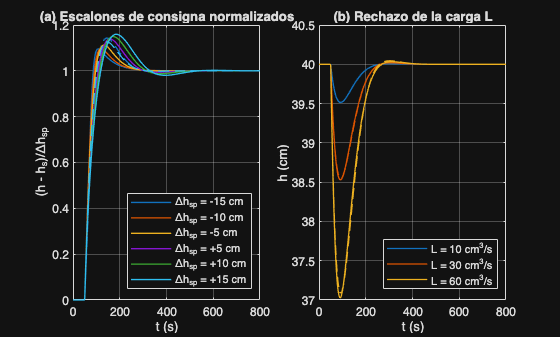


% Línea continua: no lineal; discontinua: linealizado
figure('Name', 'fig_lineal')
subplot(1,2,1)
col = lines(numel(dh7));  hl = gobjects(numel(dh7), 1);
for k = 1:numel(dh7)
    hl(k) = plot(tq7, ysp{k,1}, '-', 'Color', col(k,:), 'LineWidth', 1); hold on
    plot(tq7, ysp{k,2}, '--', 'Color', col(k,:), 'LineWidth', 1)
end
hold off; grid on; xlim([0 t7])
xlabel('t (s)'); ylabel('(h - h_s)/\Deltah_{sp}')
legend(hl, compose('\\Deltah_{sp} = %+d cm', dh7), 'Location', 'southeast')
title('(a) Escalones de consigna normalizados')
subplot(1,2,2)
col = lines(numel(L7));  hl = gobjects(numel(L7), 1);
for k = 1:numel(L7)
    hl(k) = plot(tq7, yL{k,1}, '-', 'Color', col(k,:), 'LineWidth', 1); hold on
    plot(tq7, yL{k,2}, '--', 'Color', col(k,:), 'LineWidth', 1)
end
hold off; grid on; xlim([0 t7])
xlabel('t (s)'); ylabel('h (cm)')
legend(hl, compose('L = %d cm^3/s', L7), 'Location', 'southeast')
title('(b) Rechazo de la carga L')

## Funciones Principales

function dy = modelo(y, u, p)
    % EDO no lineal del tanque cónico con PI; y = [h; z], u = [hsp; L]
    h = y(1);  z = y(2);
    e = u(1) - h;
    Q = min(max(p.Qs + p.Kp*e + p.Ki*z, p.Qmin), p.Qmax);
    dy = [p.alpha*(Q - u(2))/h^2 - p.beta/h^(3/2); e];
end

function dy = modelo_lineal(y, u, p)
    % Modelo linealizado alrededor de hs con el mismo PI
    h = y(1);  z = y(2);
    e = u(1) - h;
    Q = min(max(p.Qs + p.Kp*e + p.Ki*z, p.Qmin), p.Qmax);
    a = p.beta/(2*p.hs^(5/2));
    b = p.alpha/p.hs^2;
    dy = [-a*(h - p.hs) + b*((Q - p.Qs) - (u(2) - p.Ls)); e];
end

function u = entradas(t, p)
    % Consigna y carga escalonadas
    u = [p.hsp0 + p.dhsp*(t >= p.tsp); p.Ls + p.Lamp*(t >= p.tL)];
end

function Q = caudal(t, Y, p)
    % Caudal saturado a lo largo de una trayectoria
    Q = zeros(numel(t), 1);
    for i = 1:numel(t)
        u = entradas(t(i), p);
        Q(i) = min(max(p.Qs + p.Kp*(u(1) - Y(i,1)) + p.Ki*Y(i,2), p.Qmin), p.Qmax);
    end
end

function ok = admisible(y)
    % El modelo exige h > 0 y valores reales finitos
    ok = isreal(y) && all(isfinite(y)) && y(1) > 0;
end

function [t, Y, nF, falla] = euler(f, tramos, y0, dt)
    % Euler explícito; cada tramo se integra sin cruzar sus extremos
    t = tramos(1);  Y = y0(:)';  y = y0(:);  nF = 0;  falla = false;
    for k = 1:numel(tramos)-1
        ta = tramos(k);  tb = tramos(k+1);  tm = (ta + tb)/2;
        n = ceil((tb - ta)/dt - 1e-9);
        h = (tb - ta)/n;
        for i = 1:n
            y = y + h*f(ta + (i-1)*h, y, tm);
            nF = nF + 1;
            if ~admisible(y)
                falla = true;
                return
            end
            t(end+1, 1) = ta + i*h;
            Y(end+1, :) = y';
        end
        t(end) = tb;
    end
end

function [t, Y, nF, falla] = rk4(f, tramos, y0, dt)
    % Runge-Kutta clásico de cuarto orden por tramos
    t = tramos(1);  Y = y0(:)';  y = y0(:);  nF = 0;  falla = false;
    for k = 1:numel(tramos)-1
        ta = tramos(k);  tb = tramos(k+1);  tm = (ta + tb)/2;
        n = ceil((tb - ta)/dt - 1e-9);
        h = (tb - ta)/n;
        for i = 1:n
            ti = ta + (i-1)*h;
            k1 = f(ti, y, tm);
            k2 = f(ti + h/2, y + h/2*k1, tm);
            k3 = f(ti + h/2, y + h/2*k2, tm);
            k4 = f(ti + h, y + h*k3, tm);
            y = y + h/6*(k1 + 2*k2 + 2*k3 + k4);
            nF = nF + 4;
            if ~admisible(y)
                falla = true;
                return
            end
            t(end+1, 1) = ta + i*h;
            Y(end+1, :) = y';
        end
        t(end) = tb;
    end
end

function [t, Y, nF, est] = cash_karp(f, tramos, y0, op, tout)
    % Cash-Karp 4(5) con paso adaptativo; avanza con la solución de orden 5
    if nargin < 5, tout = []; end
    c = [0 1/5 3/10 3/5 1 7/8];
    A = [0 0 0 0 0;
         1/5 0 0 0 0;
         3/40 9/40 0 0 0;
         3/10 -9/10 6/5 0 0;
         -11/54 5/2 -70/27 35/27 0;
         1631/55296 175/512 575/13824 44275/110592 253/4096];
    b5 = [37/378 0 250/621 125/594 0 512/1771];
    b4 = [2825/27648 0 18575/48384 13525/55296 277/14336 1/4];
    y = y0(:);  m = numel(y);
    t = tramos(1);  Y = y';  nF = 0;
    est = struct('nacc', 0, 'nrec', 0, 'tacc', [], 'hacc', [], 'trej', [], 'hrej', [], ...
        'falla', false);
    for k = 1:numel(tramos)-1
        ta = tramos(k);  tb = tramos(k+1);  tm = (ta + tb)/2;
        obj = [sort(tout(tout > ta & tout < tb)); tb];  % instantes que deben alcanzarse
        j = 1;  ti = ta;  h = op.h0;                   % se reinicia el paso en cada tramo
        while ti < tb
            hp = min(h, obj(j) - ti);
            K = zeros(m, 6);
            K(:,1) = f(ti, y, tm);
            for s = 2:6
                K(:,s) = f(ti + c(s)*hp, y + hp*K(:,1:s-1)*A(s,1:s-1)', tm);
            end
            nF = nF + 6;
            y5 = y + hp*K*b5';
            y4 = y + hp*K*b4';
            if admisible(y5)
                sc = op.atol + op.rtol*max(abs(y), abs(y5));
                err = max(abs(y5 - y4)./sc);
            else
                err = Inf;
            end
            if err <= 1
                if hp == obj(j) - ti
                    ti = obj(j);  j = j + 1;
                else
                    ti = ti + hp;
                end
                y = y5;
                t(end+1, 1) = ti;  Y(end+1, :) = y';
                est.nacc = est.nacc + 1;
                est.tacc(end+1) = ti;  est.hacc(end+1) = hp;
                hn = hp*min(op.fmax, max(op.fmin, op.S*err^(-1/5)));
                if hp < h, hn = max(hn, h); end    % paso recortado por un objetivo
                h = hn;
            else
                est.nrec = est.nrec + 1;
                est.trej(end+1) = ti + hp;  est.hrej(end+1) = hp;
                h = hp*max(op.fmin, op.S*err^(-1/5));
                if h < 1e-12*max(1, abs(ti))
                    est.falla = true;
                    return
                end
            end
        end
    end
end

function Yq = referencia(f, tramos, y0, tq, tol)
    % Solución de referencia: Cash-Karp con tolerancias estrictas en los instantes tq
    if nargin < 5, tol = 1e-12; end
    op = struct('rtol', tol, 'atol', tol, 'h0', 1e-2, 'S', 0.9, 'fmin', 0.2, 'fmax', 5);
    [t, Y] = cash_karp(f, tramos, y0, op, tq(:));
    [~, idx] = ismember(tq(:), t);
    Yq = Y(idx, :);
end

function E = error_inf(t, Y, f, tramos, y0)
    % Error máximo del nivel frente a la referencia en los nodos del método
    Yr = referencia(f, tramos, y0, t);
    E = max(abs(Y(:,1) - Yr(:,1)));
end

function [dtE, dtR, dtC] = limite_paso(Acl)
    % Paso máximo con |R(dt*lambda)| <= 1 para todos los polos del lazo lineal
    lam = eig(Acl);
    A = [0 0 0 0 0 0;
         1/5 0 0 0 0 0;
         3/40 9/40 0 0 0 0;
         3/10 -9/10 6/5 0 0 0;
         -11/54 5/2 -70/27 35/27 0 0;
         1631/55296 175/512 575/13824 44275/110592 253/4096 0];
    b5 = [37/378 0 250/621 125/594 0 512/1771];
    RE = @(z) 1 + z;
    RR = @(z) 1 + z + z.^2/2 + z.^3/6 + z.^4/24;
    RC = @(z) 1 + z*b5*((eye(6) - z*A)\ones(6,1));  % función de estabilidad de Cash-Karp
    dtE = Inf;  dtR = Inf;  dtC = Inf;
    for i = 1:numel(lam)
        dtE = min(dtE, primer_cruce(RE, lam(i)));
        dtR = min(dtR, primer_cruce(RR, lam(i)));
        dtC = min(dtC, primer_cruce(RC, lam(i)));
    end
end

function dt = primer_cruce(R, lam)
    % Primer dt en que |R(dt*lambda)| supera 1
    d = linspace(0, 10/abs(lam), 4001);
    d = d(2:end);
    g = zeros(size(d));
    for i = 1:numel(d)
        g(i) = abs(R(d(i)*lam)) - 1;
    end
    i = find(g > 0, 1);
    if g(i-1) == 0
        dt = d(i-1);
    else
        dt = fzero(@(x) abs(R(x*lam)) - 1, [d(i-1) d(i)]);
    end
end

function [Acl, dtE, dtR, dtC] = limite_paso_nivel(p, h)
    % Lazo linealizado en el equilibrio de nivel h con las ganancias nominales
    ak = p.beta/(2*h^(5/2));
    bk = p.alpha/h^2;
    Acl = [-(ak + bk*p.Kp), bk*p.Ki; -1, 0];
    [dtE, dtR, dtC] = limite_paso(Acl);
end

function s = clasificar(t, Y, falla, p)
    % Estado numérico de una simulación de regulación
    if falla
        s = "h <= 0";
    elseif any(Y(:,1) < p.hmin | Y(:,1) > p.hmax)
        s = "fuera de rango";
    elseif max(abs(Y(t >= 0.8*t(end), 1) - p.hsp0)) > 0.05
        s = "no converge";
    else
        s = "converge";
    end
end

function m = metricas_escalon(t, h, t0, t1, hini, hfin)
    % Tiempo de subida (10-90 %), sobreimpulso, establecimiento (2 %) y error final
    idx = t >= t0 & t <= t1;
    tt = t(idx) - t0;  hh = h(idx);
    y = (hh - hini)/(hfin - hini);
    m.tr = cruce(tt, y, 0.9) - cruce(tt, y, 0.1);
    m.Mp = 100*max(0, max(y) - 1);
    m.ts = tiempo_banda(tt, hh - hfin, 0.02*abs(hfin - hini));
    m.ess = abs(hfin - hh(end));
end

function m = metricas_carga(t, h, t0, t1, hsp, banda)
    % Desviación máxima, tiempo de recuperación e IAE ante una carga
    idx = t >= t0 & t <= t1;
    tt = t(idx) - t0;  e = h(idx) - hsp;
    m.dmax = max(abs(e));
    m.trec = tiempo_banda(tt, e, banda);
    m.IAE = trapz(tt, abs(e));
end

function m = indicadores(t, Y, p)
    % Indicadores del escenario base (escalón de consigna y carga)
    m = metricas_escalon(t, Y(:,1), p.tsp, p.tL, p.hsp0, p.hsp0 + p.dhsp);
    mc = metricas_carga(t, Y(:,1), p.tL, t(end), p.hsp0 + p.dhsp, 0.05);
    m.dmax = mc.dmax;  m.trec = mc.trec;  m.IAE = mc.IAE;
end

function tc = cruce(t, y, v)
    % Primer instante en que y alcanza v (interpolación lineal)
    i = find(y >= v, 1);
    if isempty(i), tc = NaN; return, end
    if i == 1, tc = t(1); return, end
    tc = t(i-1) + (v - y(i-1))*(t(i) - t(i-1))/(y(i) - y(i-1));
end

function ts = tiempo_banda(t, e, banda)
    % Último instante en que |e| sale de la banda
    i = find(abs(e) > banda, 1, 'last');
    if isempty(i)
        ts = 0;
    elseif i == numel(t)
        ts = NaN;
    else
        bi = sign(e(i))*banda;
        ts = t(i) + (bi - e(i))*(t(i+1) - t(i))/(e(i+1) - e(i));
    end
end